clc;
clear;
datapath = "D:\Datasets\Color Compensation\"

datapath = "D:\Datasets\Color Compensation\"

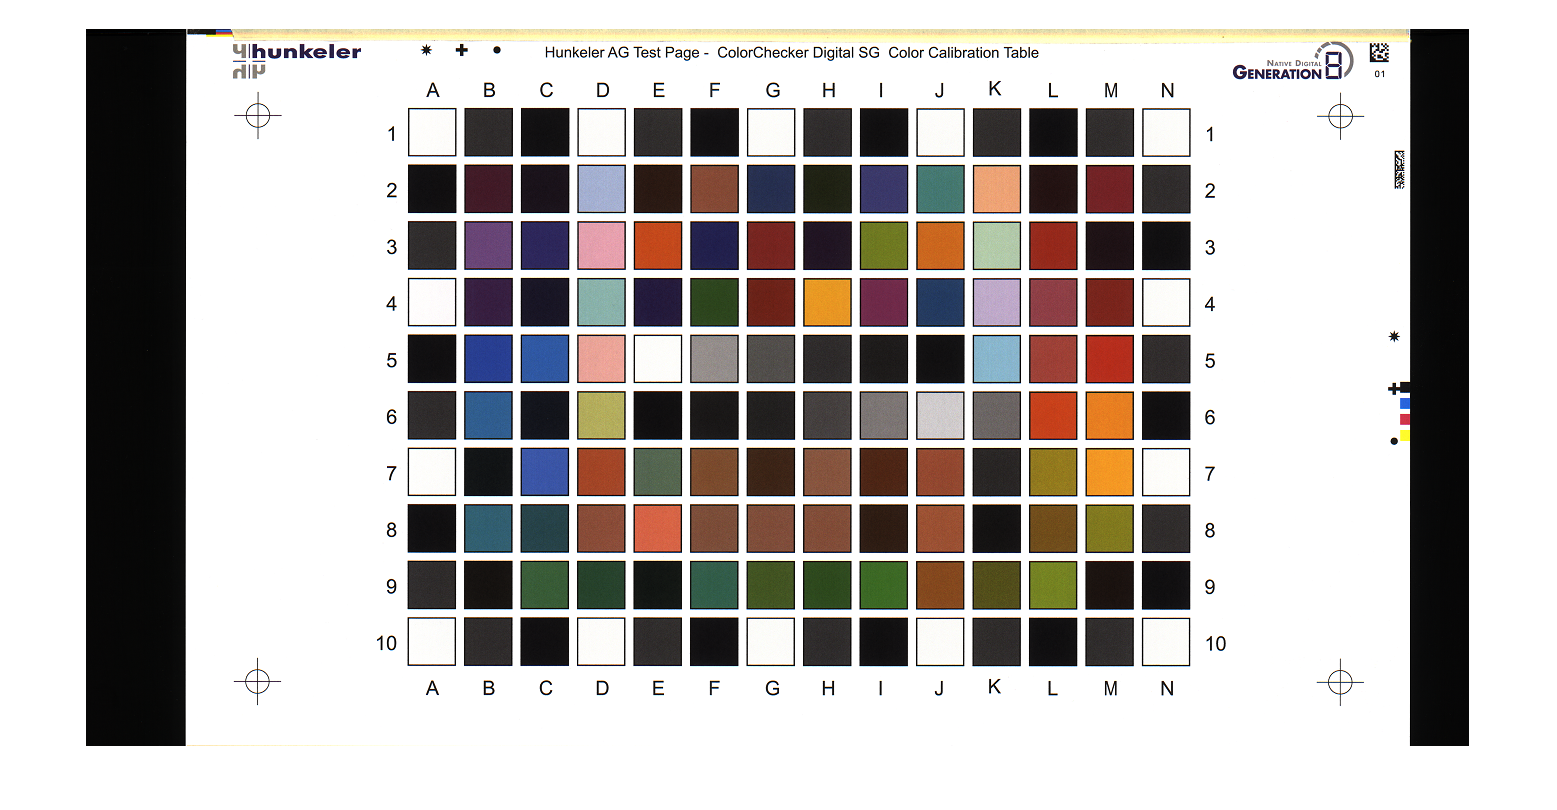

im = imread(datapath + "Gamut_Scan_rid.bmp");
master = imread(datapath + "Gamut_Master_RID.bmp");
imshow(im);

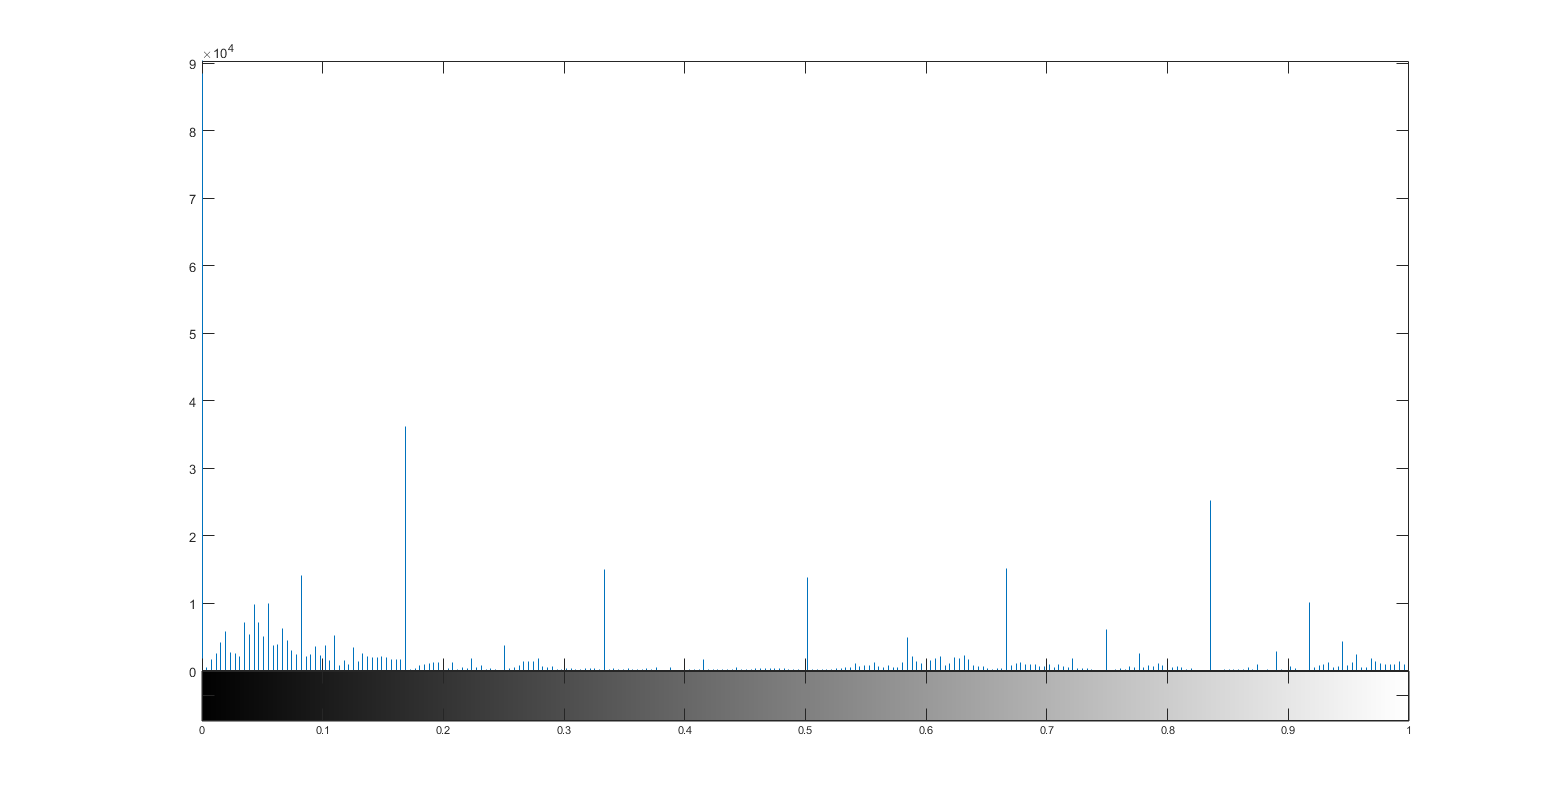

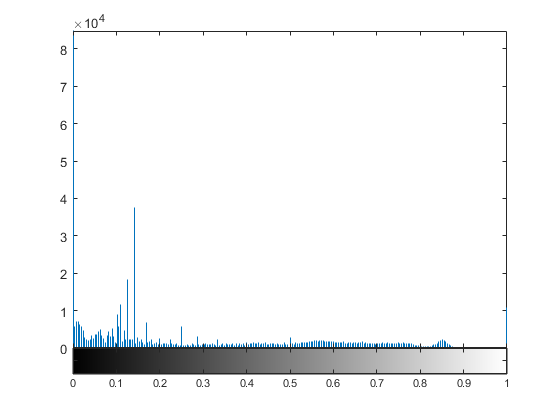

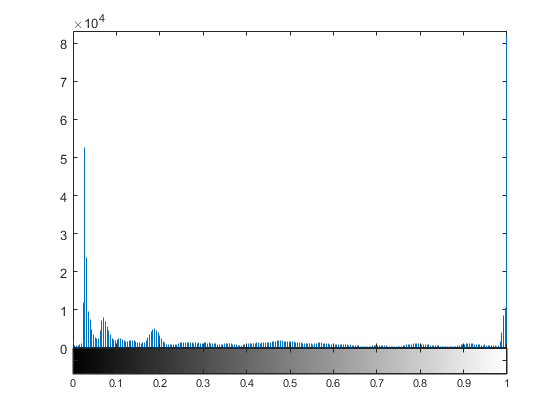

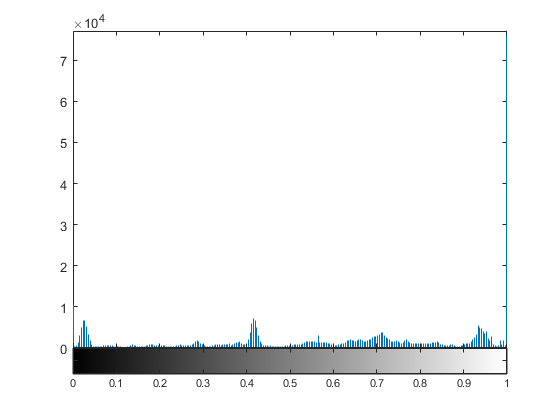

HSV = rgb2hsv(im);
H = HSV(:,:,1);
S = HSV(:,:,2);
V = HSV(:,:,3);

HSVmaster = rgb2hsv(master);
Hmaster = HSVmaster(:,:,1);
Smaster = HSVmaster(:,:,2);
Vmaster = HSVmaster(:,:,3);

for i = 1:3
    figure(i);
    imhist(HSV(:,:,i));
    figure(i+1);
    imhist(HSVmaster(:,:,i));
end

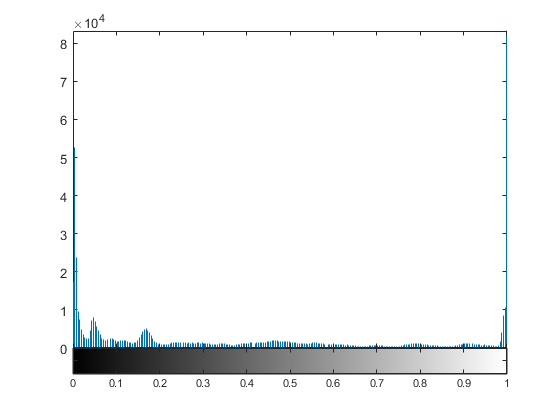

Venh = imadjust(V);
figure(2)
imhist(Venh);

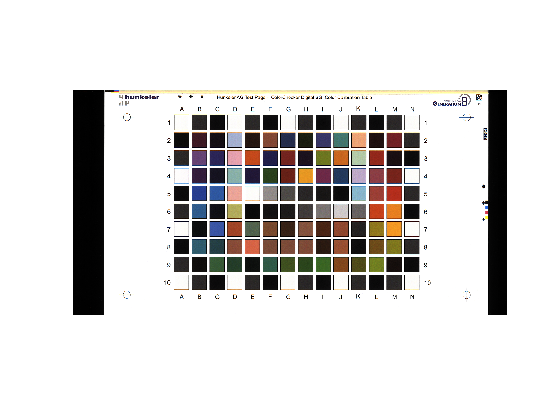


HSVenh = cat(3, H, S, Venh);
HSV = hsv2rgb(HSVenh);
imshow(HSV);


imwrite(HSV, datapath + "enh.bmp");